# Errores de redondeo y de truncamiento

## Errores de truncamiento y redondeo en espaciado

Podemos observar en el anterior pedazo de código como funciona el espaciado en los números en MATLAB, a mayor el número, más grande el espaciado entre ellos, podemos ver los diferentes intervalos de espaciado, cada $2^i$, tenemos un diferente espaciado, incrementando en tamaño con respecto al tamaño de $i$.

### Espaciado absoluto

El espaciado absoluto se refiere a cuantas unidades de `eps` hay entre dos números.

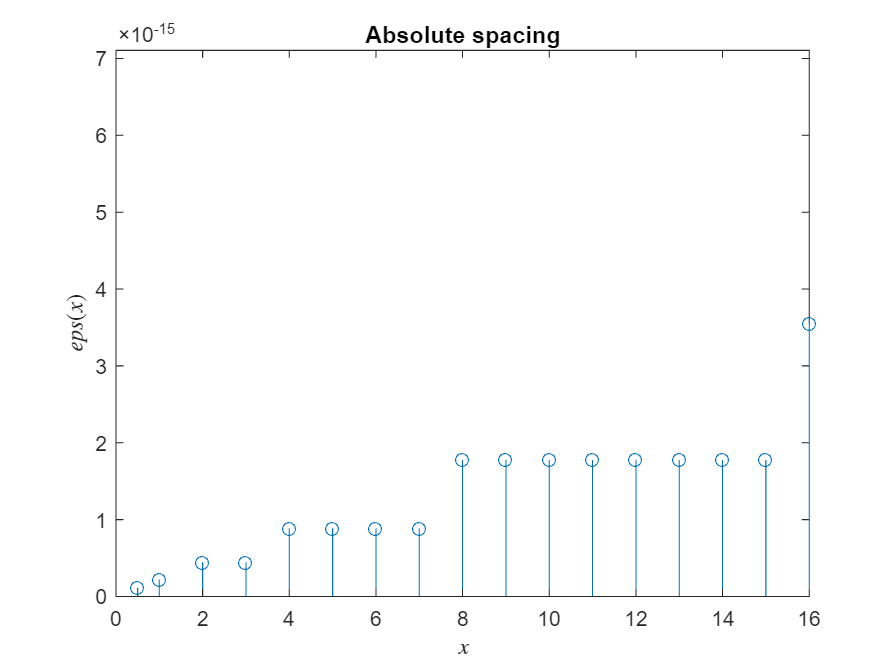

x = [1/2 1:16];
spaces = eps(x);
stem(x, spaces)
axis([0 x(end) 0 2*eps(x(end))])
title('Absolute spacing')
xlabel('$x$','interpreter','latex')
ylabel('$eps(x)$','interpreter','latex')

### Espaciado relativo

El espaciado absoluto se refiere a cuantas unidades de `eps` hay entre dos números dividido por el número en cuestión, utilizaremos mucho más el espaciado relativo que el absoluto.

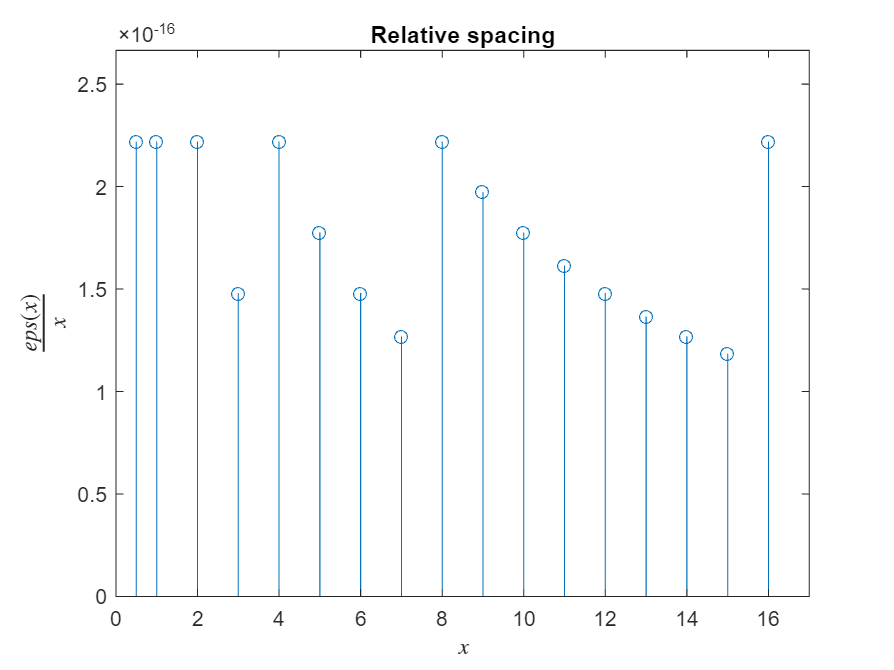

rSpaces = eps(x)./x;
stem(x, rSpaces)
axis([0 x(end)+1 0 1.2*eps(x(end))/x(end)])
title('Relative spacing')
xlabel('$x$','interpreter','latex')
ylabel('$\frac{eps(x)}{x}$','interpreter','latex')

## Ejemplos de errores de redondeo y truncación

isequal(1 - 3*(4/3 - 1), 0);
isequal(sum(0.1*ones(1,10)), 1);
isequal(sin(pi), 0);

### Errores de "suma perdida"

Si sucede que un número es lo suficientemente pequeño para caer dentro del espacio "vacio" generado por `eps` entre un número y otro, se hace una "suma perdida", lo que significa que MATLAB considera inconsecuente al número pequeño, lo que hace que se pierda el valor de la suma, algunos ejemplos son

s1 = 1e-16;
s2 = s1 +1;
s3 = s2 -1;

isequal(s2, 1)

ans = logical
   1


isequal(s3, 0)

ans = logical
   1



a1 = (1 + 1e-16) + 1e-16

a1 = 1

num2hex(a1)

ans = '3ff0000000000000'

a2 = 1 + (1e-16 + 1e-16)

a2 = 1.0000

num2hex(a2)

ans = '3ff0000000000001'


a = 1;
b = -50000000;
c = 1;


### Errores de cancelación en raíces

x1 = (-b + sqrt(b^2 - 4*a*c))/(2*a)

x1 = 5.0000e+07

x2 = (-b - sqrt(b^2 - 4*a*c))/(2*a)

x2 = 1.8626e-08


x12 = roots([a b c])

x12 = 1.0e+07 *

    5.0000
    0.0000


# Raíces y optimización

Existen dos tipos principales de métodos para encontrar raíces

- Métodos cerrados: bisección, interpolación lineal.

- Métodos abiertos: Newton-Raphson, secante, punto fijo.

En los métodos cerrados requerimos un intervalo cerrado en donde se encuentra una raíz, en los métodos abiertos, mientras le demos un punto en el intervalo antes definido, funcionará.

## Bisección

Muy similar a la búsqueda binaria, iremos haciendo la bisección del intervalo dado